# Transistor Quiz

10 Oct 23 B.R.

Quiz testing your knowledge of transistors in linear and saturated states. Questions are based on the circuit in Fig. 1. Assume Vbe = .65V when the transistor is on, $\beta > 100$ and the LED has $V_f = 2V$.

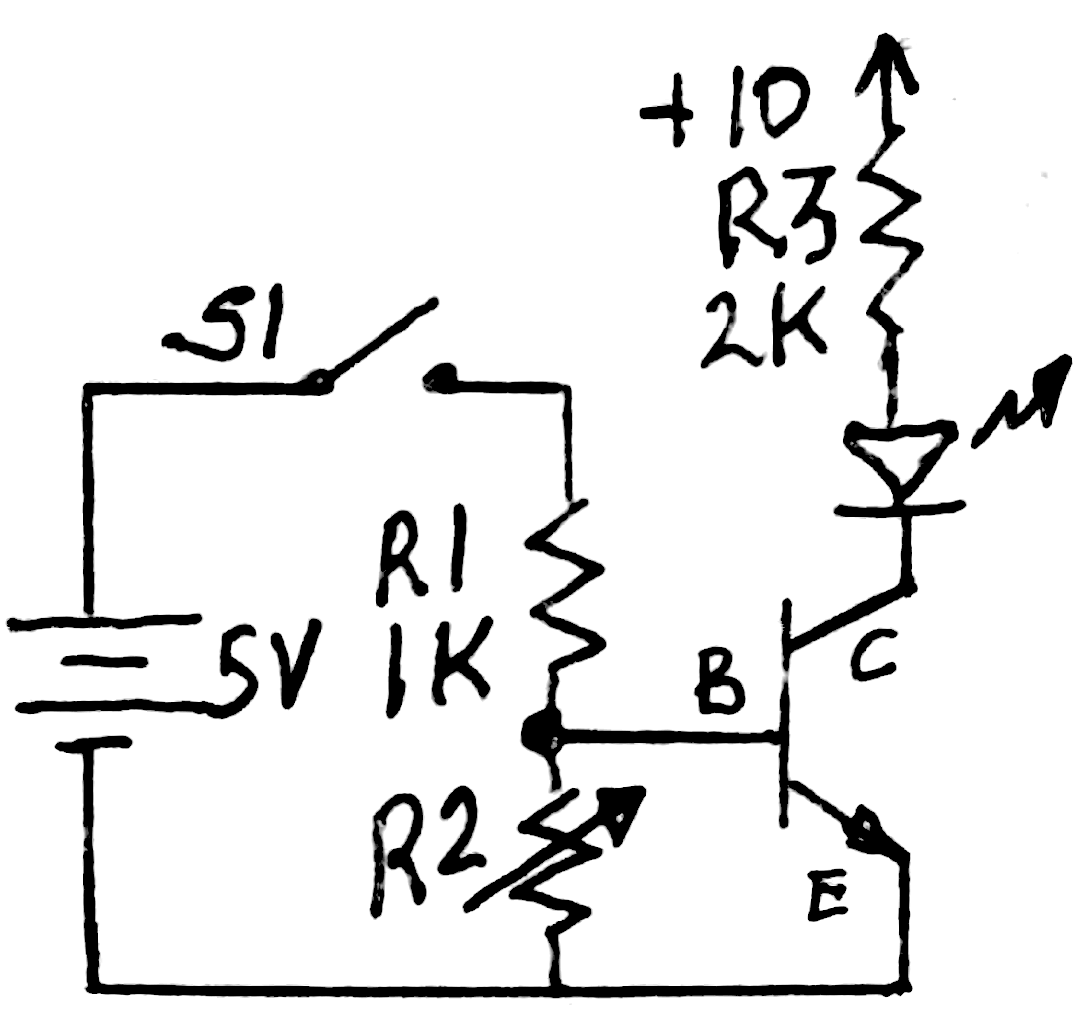

Fig. 1. Quiz circuit.

1. R2 = 1k, S1 is open, what is $V_B$, the voltage on the base and across R2, in volts?

answer(1) = 1;

2. R2 = 1k, S1 is now closed, what is $V_B$, the voltage across R2, in volts? 

answer(2) = 2;

3. R2 = 1k, S1 is open, what is the LED current in mA? 

answer(3) = 3;

4. R2 = 1k, S1 is open, what is Vce, the voltage between the transistor's collector and emitter, in volts?

answer(4) = 4;

5.  R2 = 1k, S1 is closed, what is the LED current in mA?

answer(5) = 5;

6. With S1 closed, as R changes from $1k\Omega$ to $200\Omega$, the LED will: 1. brighten, 2. dim, 3. turn off, 4. stay the same brightness? Enter your numerical choice (1:4)

answer(6) = 6;

7. With S1 closed, at what approximate value of R (in $k\Omega$) will the LED start dimming, in ohms?

answer(7) = 7;

==============================================================================

score = sum(abs(answer - [0 .65 0 10 4 4 .14]) < .1);
fprintf('%d right, %d wrong, %.2f%%\n',score, length(answer)-score, ...
    score/length(answer)*100);

0 right, 7 wrong, 0.00%


### Detailed solutions

- Students may not realize the open switch S1 results in R1 and R2 only "seeing" ground. There is no current through the open circuit, and KVL for the left loop says: -5V + $V_{S1} + 0mA * (R1+R2) = 0$, i.e., all the 5V is across the open switch S1. What about the transistor? With $V_B = 0$, the transistor's base-emitter diode is off, i.e., $Z_{BE} \approx \infty$ and it's effectively not there.

- Common mistake here is to ignore the transistor in parallel with R2. The base-emitter acts like diode, once it starts conducting, it will hold the voltage nearly constant at it's $V_f \approx 0.65V$ (Fig. 2). 

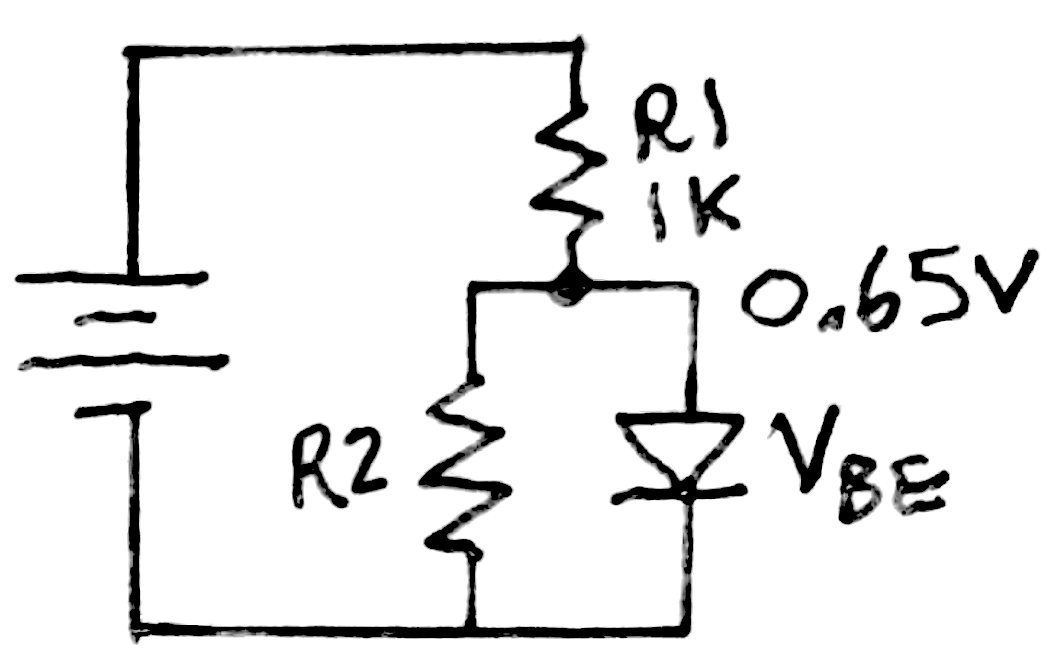

Fig. 2. Equivalent base emitter circuit with switch closed and transistor ON (active or saturated). Collector-emitter circuit not shown for simplicity.

3. Open switch --> transistor is off --> $Z_{CE} \rightarrow \infty$, $i_c \rightarrow 0$ and the LED is off. 

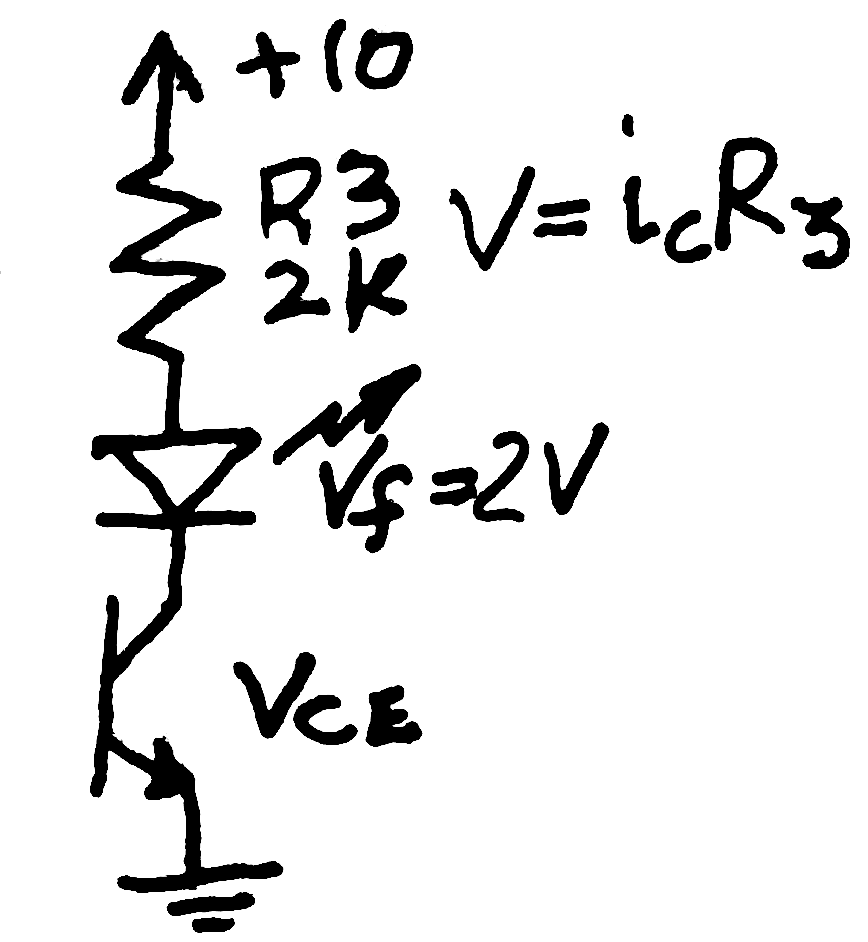

Fig. 3 Equivalent "output" circuit. 

4. Apply KVL to Fig. 3: $10V-i_c*R3-V_f-V_{CE} = 0$. With the transistor off, $i_c = 0$, the LED won't have enough (any) current to "turn on", so it's voltage = 0, hence KVL reduces to $10V-V_{CE} = 0$ or all the voltage is across the transistor -- just as it would be across an open switch as in problem 1. 

5. From Fig. 2 (switch is closed):

VR1 = 5-.65; % volts across R1
R1 = 1000; % ohms
iR1 = VR1 / R1 * 1000; % mA by ohm's law
R2 = 1000; % ohms
iR2 = 0.65 / R2 * 1000; % mA by ohm's law
ib = iR1 - iR2; % by KCL
fprintf('iR1 = %.2fmA, iR2 = %.2fmA, ib = %.2fmA\n', ...
    iR1, iR2, ib)

iR1 = 4.35mA, iR2 = 0.65mA, ib = 3.70mA


 That's enough base current to create $i_c = \beta i_b$ < 370mA. The circuit saturates when $V_{CE} \approx 0$, now the LED is conducting at $V_f = 2V$, so:

VR3 = 10 - 2; % from Fig. 3
R3 = 2e3;
iR3 = VR3/R3 * 1000; % mA
fprintf('LED current = iR3 = ic = %.2fmA\n', iR3')

LED current = iR3 = ic = 4.00mA


6. Let's simulate the circuit for a range of values of R2

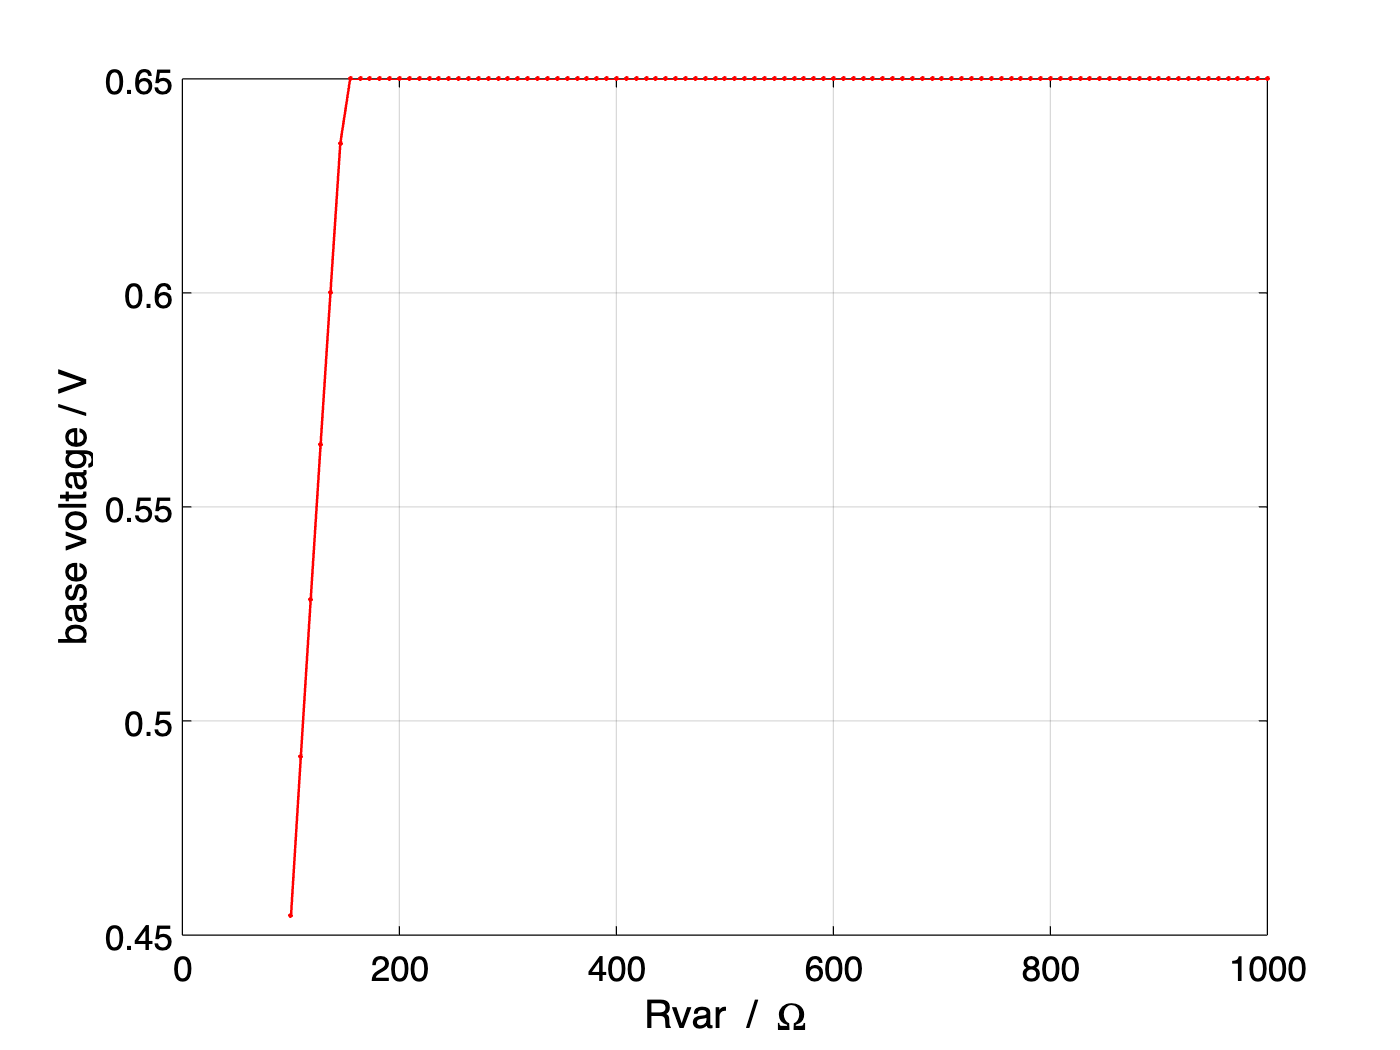

Vin = 5;
R2 = linspace(100,1e3)'; % a vector
Vb = Vin * R2 ./ (R1+R2); % if no transistor
Vb(Vb > 0.65) = 0.65; % base-emitter diode "clamp"
plot(R2, Vb,'.-'); xlabel('Rvar / \Omega'); ylabel('base voltage / V')
grid;

Transistor turns on around $150\Omega$. Compute the currents with Ohm's Law, 

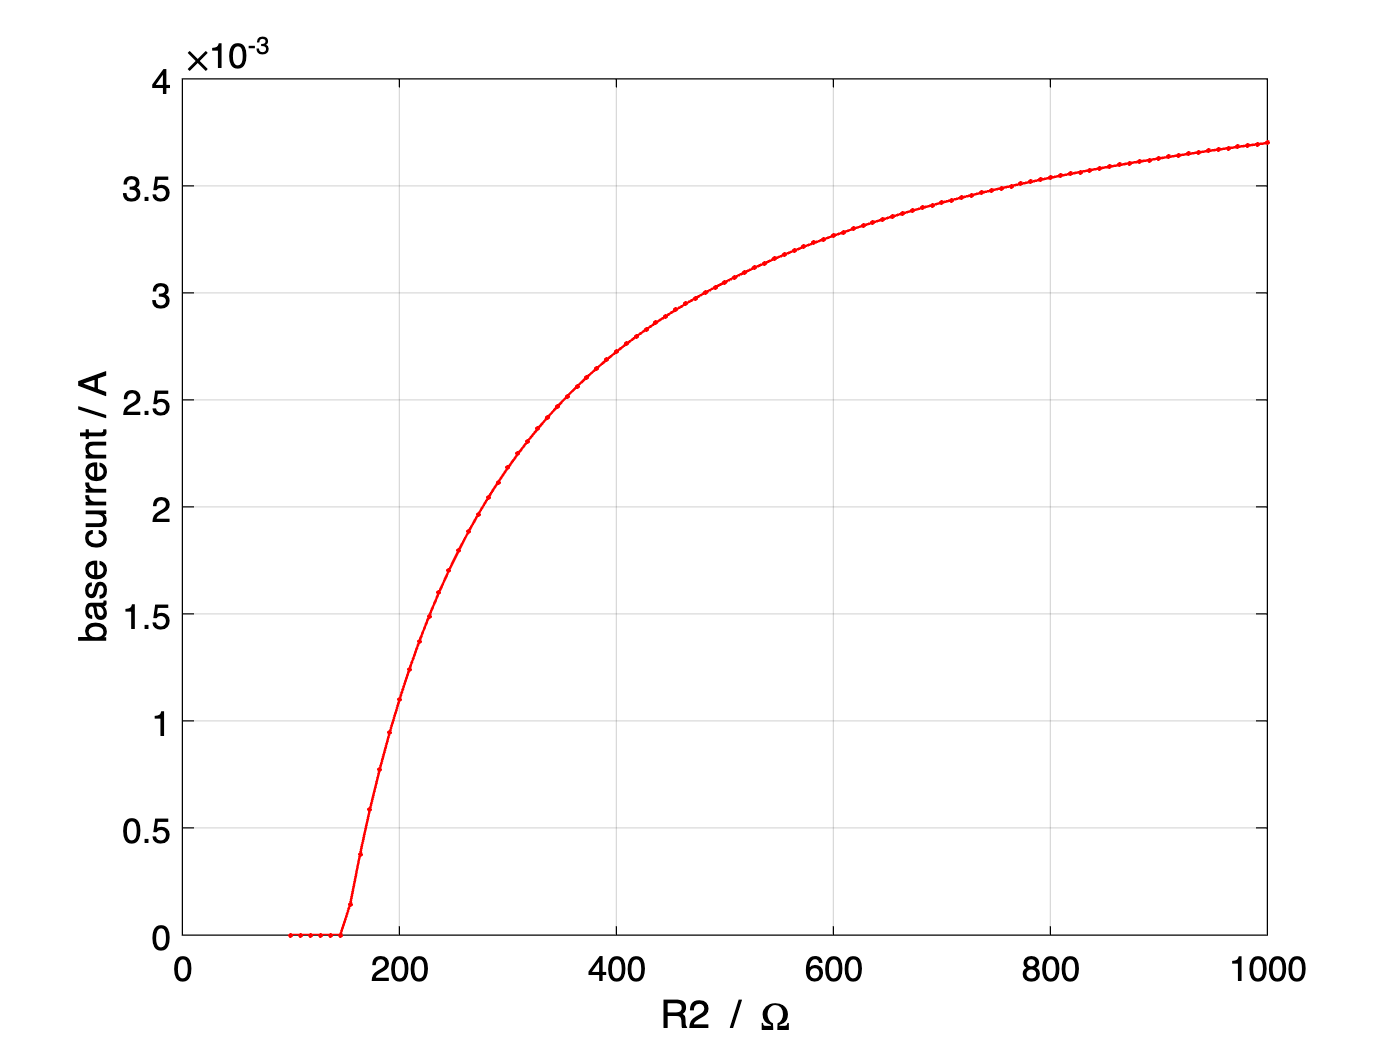

i1 = (Vin - Vb) / R1; % Ohm's Law
i2 = Vb ./ R2; % Ohm's Law 
ib = i1-i2; % KCL -- R1 current has 2 possible paths
plot(R2, ib,'.-'); grid;
xlabel('R2 / \Omega'); ylabel('base current / A')

As R2 gets larger ("resists more"), more current flows through the base. "Current takes the path of least resistance", and $Z_{BE}$ is a low resistance path *after* the base-emitter diode is forward biased. Now let's look at the output side of the transistor. The collector current could be $\beta = 100$ times greater than $i_{base}$ above, until it saturates. Saturation happens when $Z_{CE} \rightarrow 0 \Omega$, the equivalent circuit is 10V in series with $2K\Omega$ and $V_f = 2V$ of the LED. KVL says $10V + i_c*2k\Omega + V_f + V_{CE}= 0$ and in saturation $V_{CE}\rightarrow 0$ so $V_{2k} = 10-V_f = 8V%$in saturation, and Ohm's Law gives the maximum saturation current. 

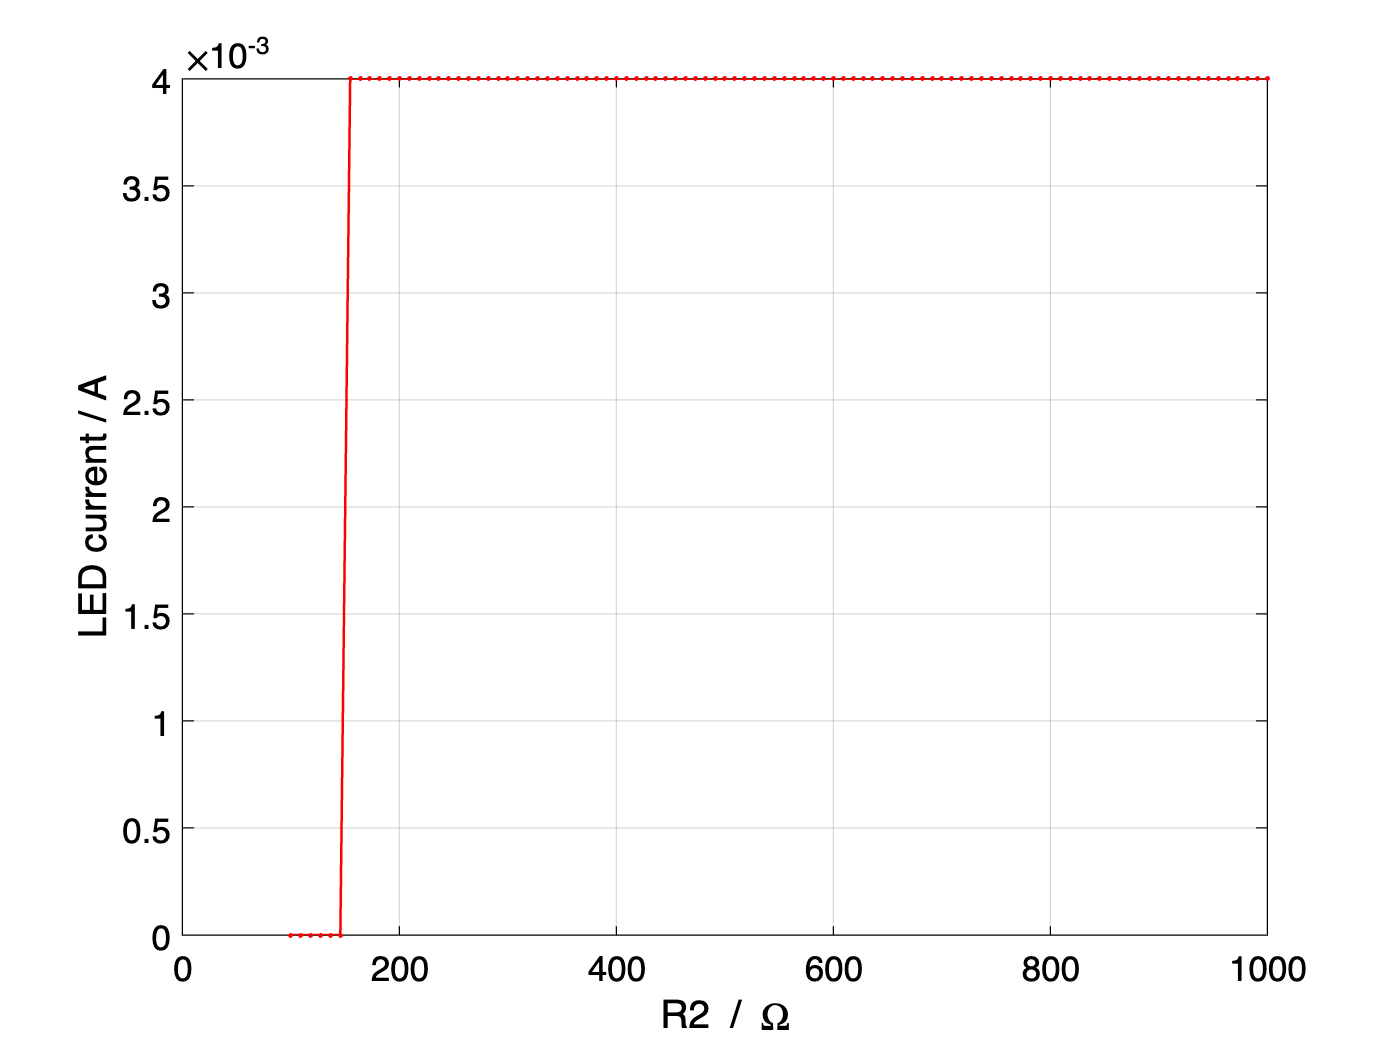

beta = 100;
ic = beta * ib; % in the transistor active region
icsat = (10-2)/2e3; % saturation current in A
ic(ic>icsat) = icsat;
plot(R2, ic,'.-'); grid;
xlabel('R2 / \Omega'); ylabel('LED current / A')

A key point is the saturation current is a *circuit* property, not an intrinsic transistor property, like $\beta$ is. For the graph's y-label, I made the inference that the collector current is the LED current. You can see why we call this circuit a switch. Although the base current takes on a range of values, the LED current jumps, here are a few of the discrete values near the corner or "knee":

fprintf('%1.2E\t',ic(4:7))

0.00E+00	8.67E-17	0.00E+00	4.00E-03	

fprintf('%1.2f\t',R2(4:7))

127.27	136.36	145.45	154.55	

 Current is <1e-16A at R2 = 145 ohms, and saturated at 4mA at R2 = 154 ohms. 

### Ebers-Moll Transistor Model

According to our model above, the LED would turn OFF for R < ~140 ohms. Is the model right?? We have ample reason to doubt it because we shouldn't expect a simplistic "piecewise linear" model to accurately replicate the transistor's behavior at its corner. Let's see if we can apply a better model, and we can find the equations at [https://en.wikipedia.org/wiki/Bipolar_junction_transistor#Large-signal_models](https://en.wikipedia.org/wiki/Bipolar_junction_transistor#Large-signal_models):

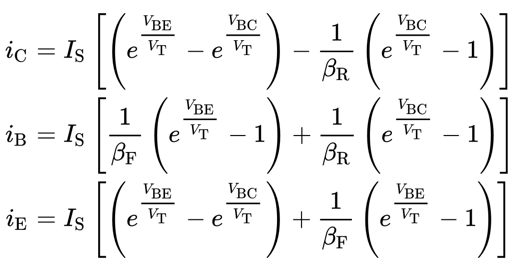

Ooohh, you should be saying, a "much better model -- why didn't we start with this?" /s. These "Ebers-Moll" equations introduce lots of parameters. Some are approximate constants given on the Wikipedia page, but some are uncertain over orders of magnitude (like $I_s$ = 1e-15 to 1e-12), and some depend on the (dynamic) state of the circuit. A good approach is to restrict the domain that we're trying to model, e.g., just to around the knee when the transistor is turning on, Vbe <~ .6V. (Fun fact: if you take the 0.6V limit off of Vb, you'll get ib and ic approaching 10E30A -- *slightly* unrealistic.) I'm not sure how to handle$V_{BC}$, because when the transistor is off, $V_{BC}$ is large. KVL says 10V-ic * 2k - $V_{LED}$ - $V_{BC}$ = 0, but ic isn't known let (it's one of the above equations that depends on $V_{BC}$, and we're not sure the LED has reached it's knee voltage yet -- that depends on ic. So there are multiple coupled equations to solve ... So I try the easiest guess: $V_{BC}$ << $V_{BE}$ = Vb, and ignore it ;-). 

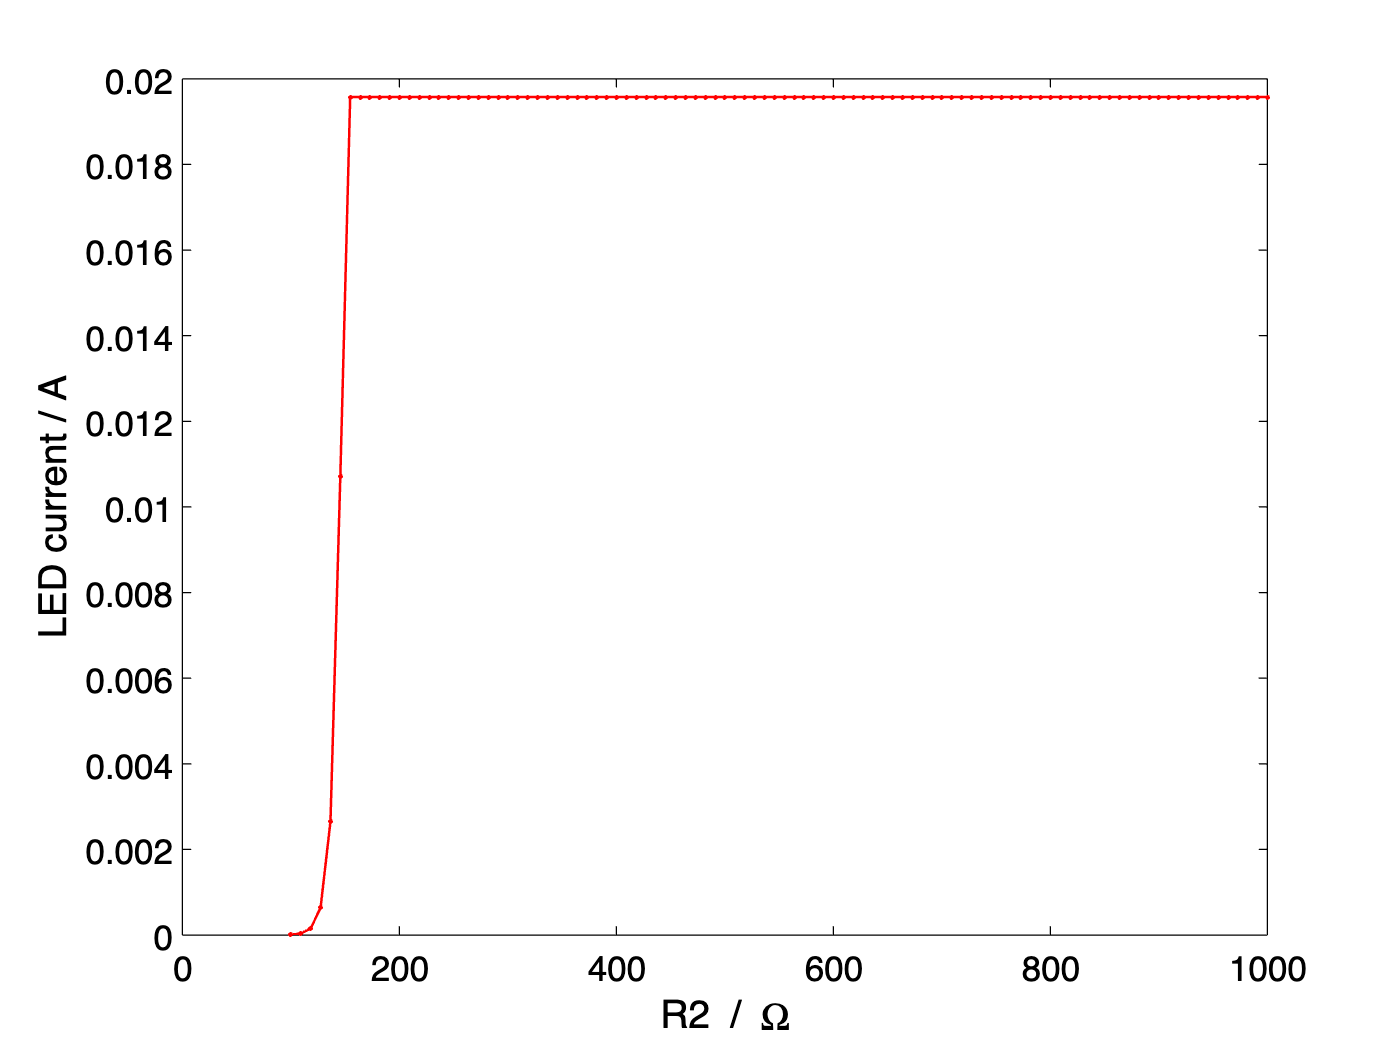

Vt = 25e-3; % thermal voltage of a transistor
bf = beta;
br = beta/10; % wild guess of reverse common emitter gain
Is = 1e-13; % 1e-15 to 1e-12, reverse saturation current
ibem = Is * (1/bf * (exp(Vb/Vt) - 1));
icem = Is * (exp(Vb/Vt));
plot(R2, icem, '.-');
xlabel('R2 / \Omega'); ylabel('LED current / A')

The saturation current is a little high -- which we could fix by decreasing` Is` (by the ratio of the right answer / wrong answer ~ 4/20). But at least Ebers-Moll predicts a more gradual turn-on at the lowest R2 values. If we `set(gca,'yscale','log')` or just replot this on a log scale: 

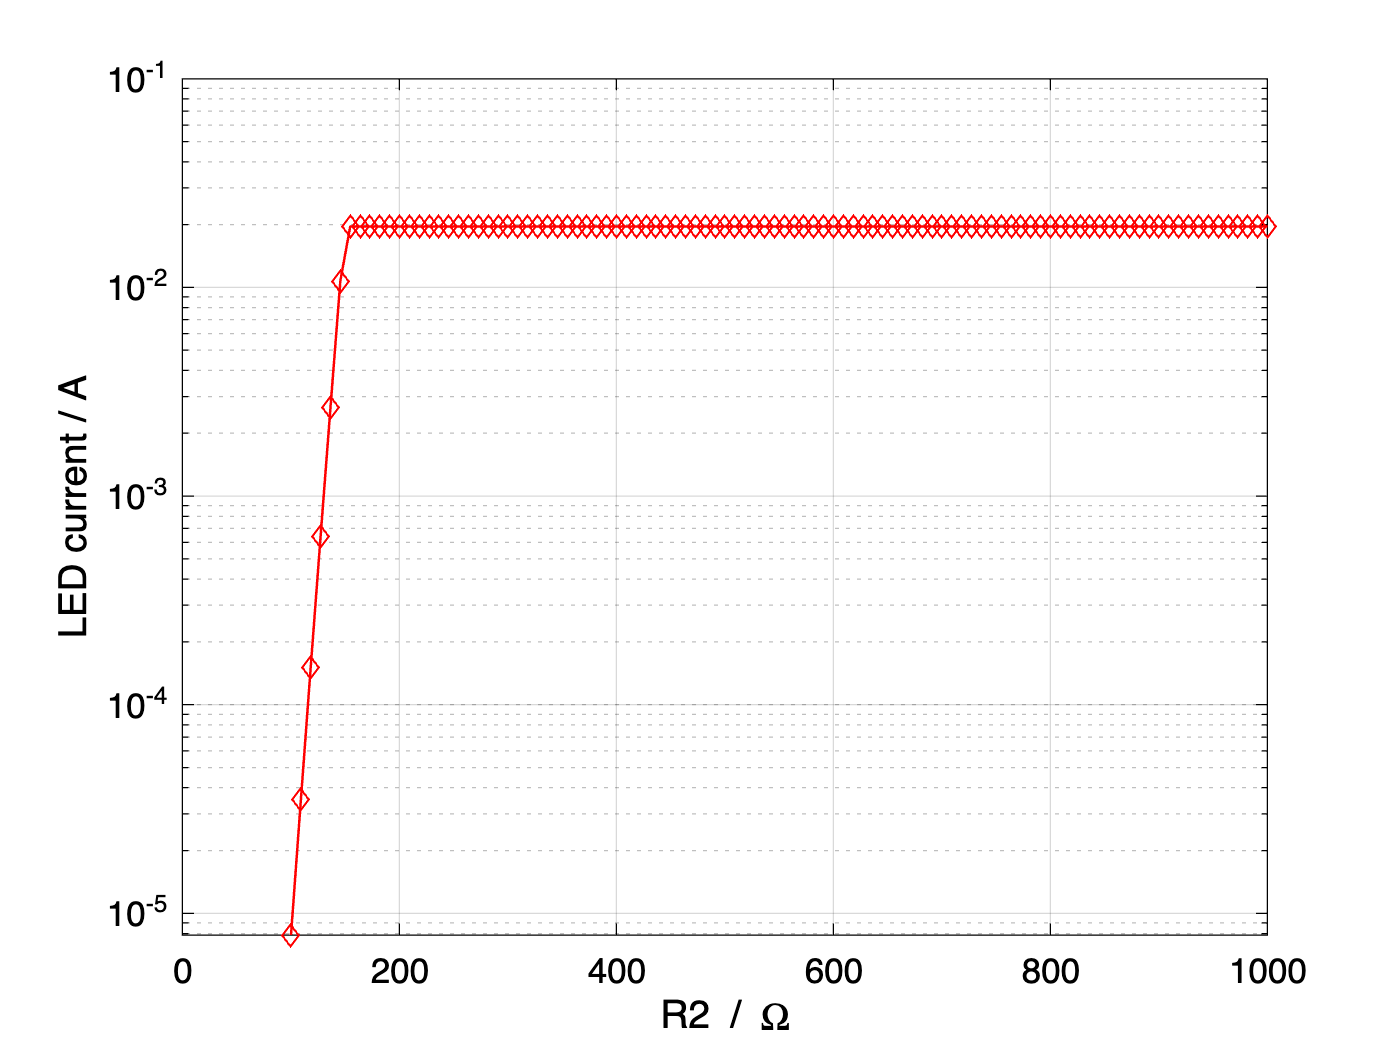

semilogy(R2, icem,'d-')
xlabel('R2 / \Omega'); ylabel('LED current / A'); grid

It predicts the LED *would* be vastly dimmer at R2 = 100 ohms, but technically not off -- with LED current ~ 8$\mu$A. Not clear if that's bright enough to see, but more importantly, not clear that we should have more confidence in this prediction's numerical value than the prior model, for the same reasons -- there are just too many ad hoc assumptions in the model.

We could attempt to build the circuit on the breadboard -- but that's actually not easy unless you can find an NPN transistor with $\beta$ = 100 ... but we could build it with our S8050 transistor with around twice that beta. We can make some predictions: if the LED is very dim, then it would be even dimmer with $\beta$ = 100. However, if it is off with $\beta$ = 200 then it would certainly be off with $\beta$ = 100. And, drum roll ... 

With Vref = 4.5V, R1=1k, R2 = 100 ohms, 10V -> 2k -> blue LED -> collector, the LED is for most practical purposes OFF. Vb measured .42V $\approx$ 4.5V * 100/(100+1k), as if the transistor were an infinite Z (left of the $V_{BE}$ knee). Replaced R2 with 200 ohms and  LED is full brightness, not visibly different than R2 = infinity, no voltage divider, ib = (4.5-.7V)/1k. The LED shuts off somewhere between R2 = 100-200 ohms. When it's off, $V_{BC}$ ~ 0.42-7.6V is large but *negative*, aaahhhhh so $e^{(V_{BC}/V_T)} \approx 0$ because the exponent is large *negative*, making the second parentheses of $i_C$ negligible compared to the first, and the 2nd term of the first parenthesis is negligible compared to the first, $e^{(V_{BE}/V_T)} \approx e^{.6/.026} \approx 10^{10}$. So that's why my guess to ignore $V_{BC}$ worked as well as it did. 

### Reflection

This is the first time I tried an Ebers-Moll model and it wasn't very illuminating nor useful, but you win some and you lose some ... What's *your *favorite transistor model? 